%SAC_agent = SAC_agents{3};
datalogger = SAC_agent.datalogger;
ref_state = SAC_agent.env.ref_state;
[~, tracked_idx] = ismember(SAC_agent.env.tracked_states, SAC_agent.env.state_vars);

for i = 1:length(datalogger.eval_ep_log)
    returns(i) = double(gather(datalogger.eval_ep_log(i).return));
end

[maxValue, maxIdx] = max(returns)

maxValue = -0.4683

maxIdx = 4

%maxIdx = 2
state = datalogger.eval_ep_log(maxIdx).state;
%state(:,tracked_idx) = ref_state(1:end-1,:) + state(:,tracked_idx);
action = datalogger.eval_ep_log(maxIdx).action;
reward = datalogger.eval_ep_log(maxIdx).reward;
nMAE = mean(abs(state(:,4)- state(:,3))) / mean(abs(state(:,4)))

nMAE = 0.3394

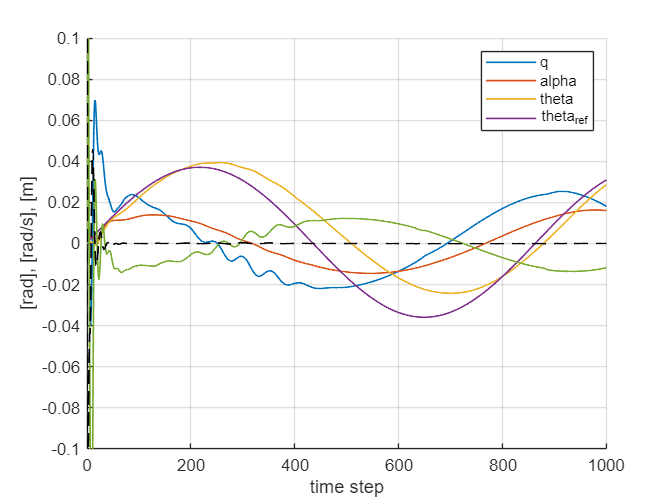


steps_per_episode = 1000;
dt = 0.01;
episode_length = steps_per_episode * dt;
time = (0:dt:episode_length)';
color = ['k', 'g', 'm', 'b', 'r', 'y', 'c', "#4DBEEE", "#77AC30", "#7E2F8E", "#EDB120", "#D95319", "#D95310"];
figure
hold on
for i = 1:width(state)
    %plot((state(:,i)), LineWidth=1, Color=color(i))
    plot((state(:,i)), LineWidth=1)
end
% plot(ref_state(:,1))
% plot(ref_state(:,2))
% plot(ref_state(:,3))

plot(action(:,1), LineWidth=1, Color='k', LineStyle='--')
% plot(action(:,2), LineWidth=1, Color='k', LineStyle=':')
% plot(action(:,3), LineWidth=1, Color='k', LineStyle='-.')
%legend('p', 'q', 'r', 'V_{TAS}', 'alpha', 'beta', 'phi', 'theta', 'h', 'p_{ref}', 'q_{ref}', '\beta_{ref}', '\delta_e', '\delta_a', '\delta_r')
legend([SAC_agent.env.state_vars_dict(SAC_agent.env.state_vars), SAC_agent.env.tracked_states_dict(SAC_agent.env.tracked_states)])
xlim([0,length(time)])
ylabel('[rad], [rad/s], [m]')
xlabel('time step')
xlim([0,length(time)])
ylim([-0.1 0.1])
%title("Episode " + maxIdx + ": nMAE(q,q_{ref}) = " + 100*nMAE + "%")
%ylim([-0.2 + (min(state(:,11))), 0.2 + (max(state(:,11)))])
grid on

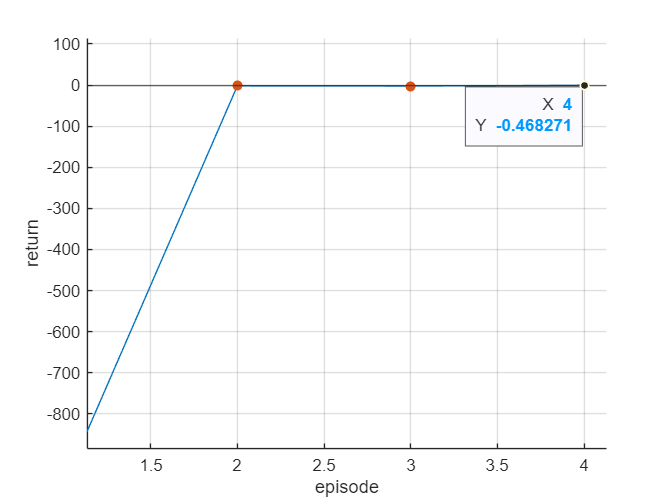


figure
hold on
plot(returns)
scatter(1:length(returns), returns, 'filled')
%plot(mean_return, LineWidth=2)
yline(0)
xlabel('episode')
ylabel('return')
hold off
grid on



figure
hold on
grid on
linestyle = ['--', ':', '-.'];
for i = 1:width(action)
    plot(action(:,i), LineWidth=1, Color='k', LineStyle=linestyle(i))
end
%legend('p', 'q', 'r', 'V_{TAS}', 'alpha', 'beta', 'phi', 'theta', 'h', 'p_{ref}', 'q_{ref}', '\beta_{ref}', '\delta_e', '\delta_a', '\delta_r')
legend('\delta_e', '\delta_a', '\delta_r', '\Delta\delta_e', '\Delta\delta_a', '\Delta\delta_r')

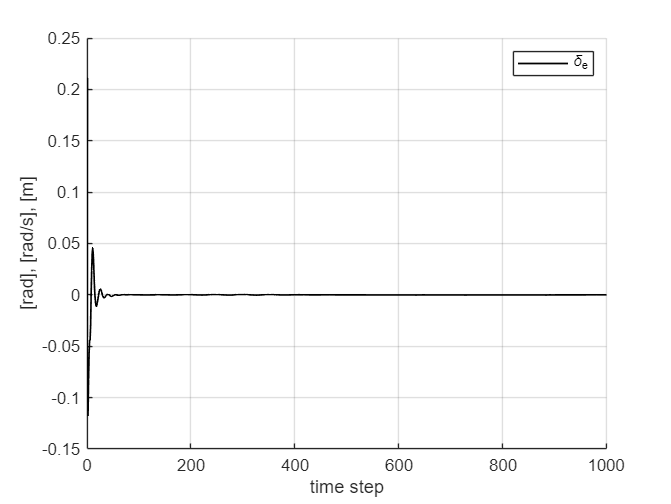

ylabel('[rad], [rad/s], [m]')
xlabel('time step')
xlim([0,length(time)])

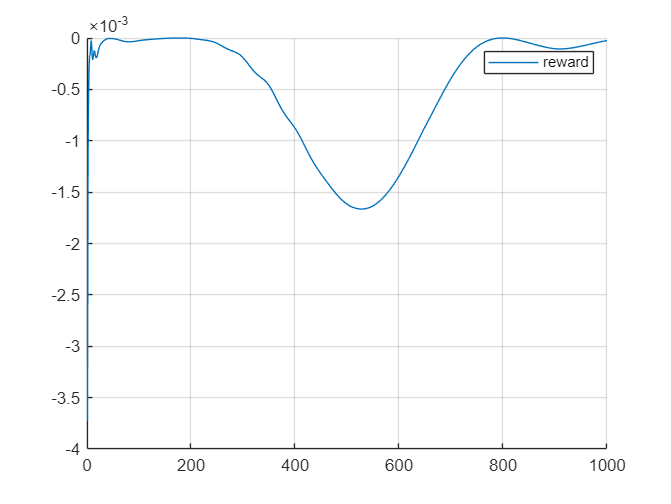

%ylim([-0.005 0.005])



figure
hold on
grid on
plot(datalogger.eval_ep_log(maxIdx).reward)
legend('reward')

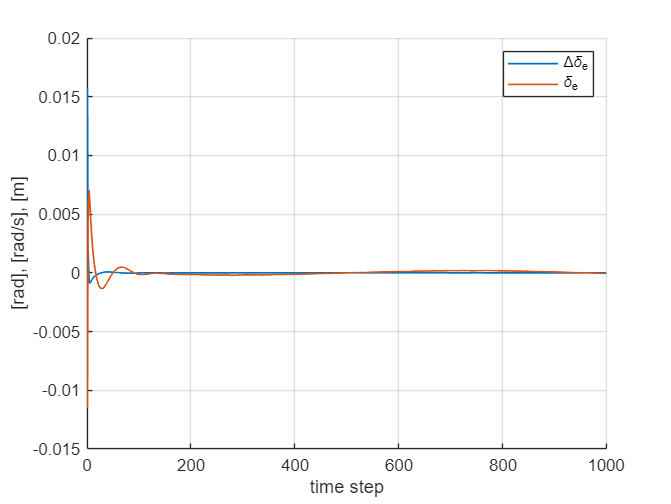


figure
hold on
grid on
plot(diff(action), LineWidth=1)
plot(action, LineWidth=1)

% legend('\delta_e', '\delta_a', '\delta_r', '\Delta\delta_e', '\Delta\delta_a', '\Delta\delta_r')

legend(["\Delta\delta_e", "\delta_e"])
ylabel('[rad], [rad/s], [m]')
xlabel('time step')
xlim([0,length(time)])

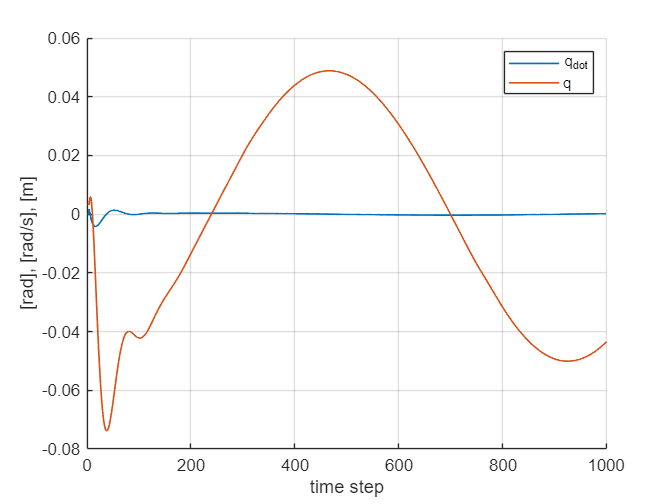

figure
hold on
grid on
plot(diff(state(:,1)), LineWidth=1)
plot(state(:,1), LineWidth=1)

legend('q_{dot}', 'q')
ylabel('[rad], [rad/s], [m]')
xlabel('time step')
xlim([0,length(time)])